# Rocket State Estimator Quaternion

Authors: John H. Lambert and Daniel J. Pearson

Version: 10/5/2023

clear variables; close all; clc;

### Initialization

% State Vector
x = [1; 0; 0; 0];
x_min = [1; 0; 0; 0];

P = eye(4); % Covariance Matrix
P_min = eye(4);

R = diag([0.000262^2, 0.000262^2, 0.00262^2]); % Measurement Noise Covariance

Q = diag([0.002^2, 0.002^2, 0.002^2, 0.002^2]); % Process Noise Covariance

g = 9.81; % [m/s/s] Gravitational Acceleration

dt = 1/40; % [s]

### Data Loading

csvLog = readtable('./data/IREC2023_FLASH_DATA.xlsx');

### Configure Low Pass Filter

filterFreq = 40; % [Hz]
cutoffFreq = 8; % [Hz]
alpha = dt / (1 / (2 * pi * cutoffFreq) + dt);

### Setup Live Plot

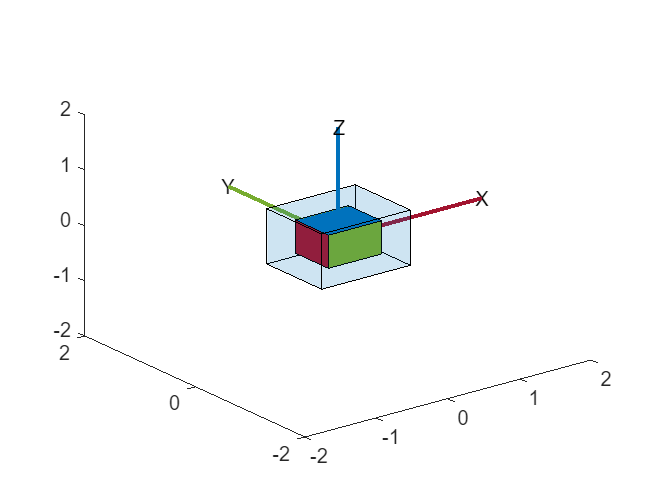

figure;
subplot(3,1,1);
xPlot = plot(NaN, NaN, '-b');
xlabel('Time');
ylabel('Roll (rad)');
title('Realtime Roll');
subplot(3,1,2);
yPlot = plot(NaN, NaN, '-g');
xlabel('Time');
ylabel('Pitch (rad)');
title('Realtime Pitch');
subplot(3,1,3);
zPlot = plot(NaN, NaN, '-r');
xlabel('Time');
ylabel('Yaw (rad)');
title('Realtime Yaw');

figure;
accelPlot = plot(NaN, NaN);
xlabel('Time');
ylabel('m/s^2');
title('Realtime Acceleration');

figure;
ax = axes;
view(3);  % Set the view to 3D
hold on;

pp = poseplot('Parent', gca);

### Estimation Loop

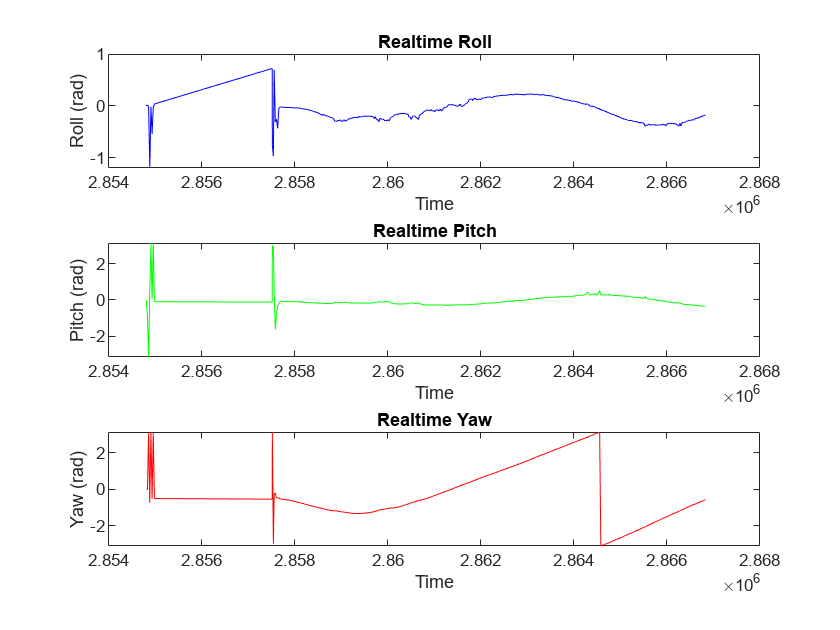

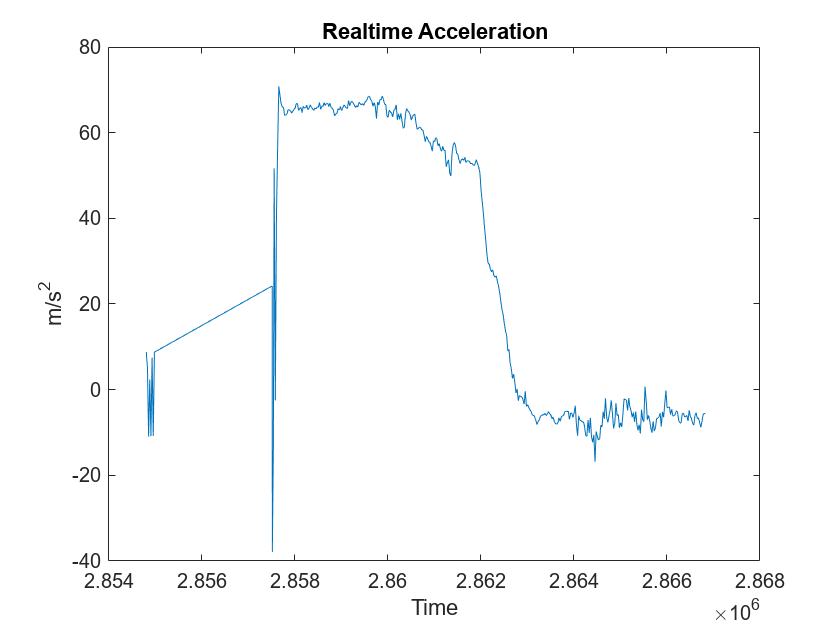

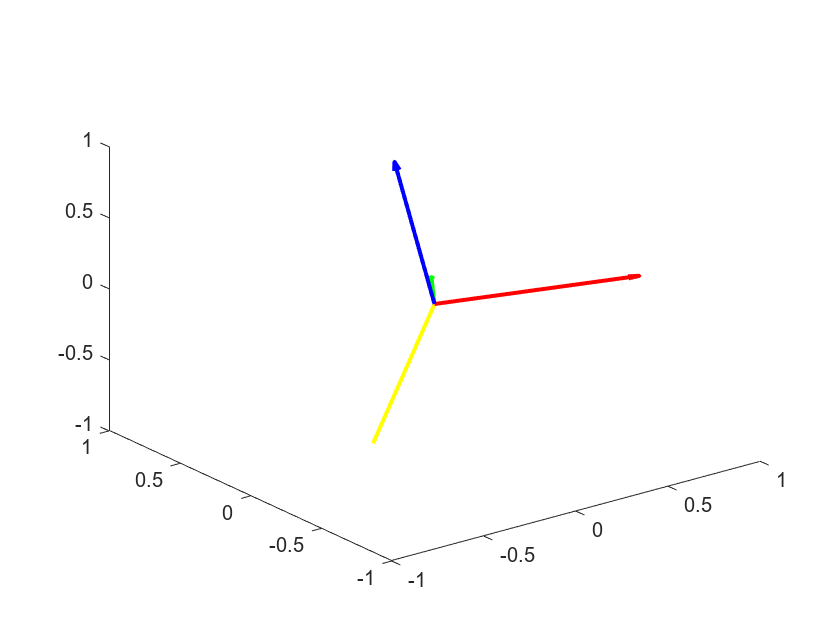

for i = 1:size(csvLog)
    % Apply conversion factor on Telemetry Log to de-compress data
    % Compression Factor - 10.0
    gyroX = (csvLog.GyroX(i) / 10.0) * (pi/180); % [rad/s]
    gyroY = (csvLog.GyroY(i) / 10.0) * (pi/180); % [rad/s]
    gyroZ = (csvLog.GyroZ(i) / 10.0) * (pi/180); % [rad/s]

    %% Apply conversion factor to Telemetry Log to de-compress data
    % Compression Factor - 100.0
    accelX = csvLog.AccelX(i) / 100.0 * 9.81; % [G]
    accelY = csvLog.AccelY(i) / 100.0 * 9.81; % [G]
    accelZ = ((csvLog.AccelZ(i) / 100.0) + 1) * 9.81; % [G]

    if i==1
        filtered_gyroX = gyroX;
        filtered_gyroY = gyroY;
        filtered_gyroZ = gyroZ;
        
        filtered_accelX = accelX;
        filtered_accelY = accelY;
        filtered_accelZ = accelZ;
    end

    filtered_gyroX = alpha * gyroX + (1 - alpha) * filtered_gyroX;
    filtered_gyroY = alpha * gyroY + (1 - alpha) * filtered_gyroY;
    filtered_gyroZ = alpha * gyroZ + (1 - alpha) * filtered_gyroZ;

    filtered_accelX = alpha * accelX + (1 - alpha) * filtered_accelX;
    filtered_accelY = alpha * accelY + (1 - alpha) * filtered_accelY;
    filtered_accelZ = alpha * accelZ + (1 - alpha) * filtered_accelZ;
   
    u = [filtered_gyroX; filtered_gyroY; filtered_gyroZ];

    y = [filtered_accelX; filtered_accelY; filtered_accelZ];

    x_min = x_min + dt*f(x, u);

    A = calculate_Jacobian_f(x_min, u);

    % P_min = P_min + A * P * A' + dt*Q;
    P_min = A*P*A' + dt*Q;

    h = h_func(x, y);

    C = calculate_Jacobian_h(x, y);

    K = P*C' / (C*P*C' + R);

    x = x_min + K * (y - h);
    
    P = (eye(4) - K * C) * P;

    axesRot = quat2rotm(x');
    
    % Use the rotation matrix to obtain grav compensated global accel
    accelGlobal = axesRot * y;
    accelGlobal(3) = accelGlobal(3) - 1;

    % Get the direction vectors for the axes
    x_axis = axesRot(:, 1);
    y_axis = axesRot(:, 2);
    z_axis = axesRot(:, 3);

    origin = [0 0 0];

    % Define the length of the axes
    axis_length = 1.0;

    cla(ax);

    % Plot the axes using quiver3
    quiver3(origin(1), origin(2), origin(3), x_axis(1)*axis_length, x_axis(2)*axis_length, x_axis(3)*axis_length, 'r', 'LineWidth', 2);
    quiver3(origin(1), origin(2), origin(3), y_axis(1)*axis_length, y_axis(2)*axis_length, y_axis(3)*axis_length, 'g', 'LineWidth', 2);
    quiver3(origin(1), origin(2), origin(3), z_axis(1)*axis_length, z_axis(2)*axis_length, z_axis(3)*axis_length, 'b', 'LineWidth', 2);
    quiver3(origin(1), origin(2), origin(3), accelGlobal(1), accelGlobal(2), accelGlobal(3), 'y', 'LineWidth', 2);

    % Set axis limits as needed
    axis([-1 1 -1 1 -1 1]); % Adjust as needed

    angles = quat2eul(x');

    currentTime = csvLog.Timestamp(i);

    x_data = get(xPlot, 'XData');
    xData = get(xPlot, 'YData');
    yData = get(yPlot, 'YData');
    zData = get(zPlot, 'YData');
    accelData = get(accelPlot, 'YData');

    x_data = [x_data, currentTime];
    xData = [xData, angles(2)];
    yData = [yData, angles(3)];
    zData = [zData, angles(1)];
    accelData = [accelData, accelGlobal(3)];

    set(xPlot, 'XData', x_data, 'YData', xData);
    set(yPlot, 'XData', x_data, 'YData', yData);
    set(zPlot, 'XData', x_data, 'YData', zData);
    set(accelPlot, 'XData', x_data, 'YData', accelData);
    % writematrix(x', 'dataLog.csv', 'WriteMode', 'append');
    % 
    % % pause(dt);
    % Refresh the plot
    drawnow;
end

function A = calculate_Jacobian_f(x, u)
%calculate_jacobian - Calculate the jacobian of the f matrix
    p = u(1);
    q = u(2);
    r = u(3);

    A = 0.5 * [
         0 -p -q -r;
         p 0 r -q;
         q -r 0 p;
         r q -p 0;
        ];
end

function C = calculate_Jacobian_h(x, y)
    % Extract quaternion components from the state vector x
    q0 = x(1);
    q1 = x(2);
    q2 = x(3);
    q3 = x(4);

    % Normalize the quaternion to ensure it represents a valid rotation
    q_norm = norm([q0, q1, q2, q3]);
    q0 = q0 / q_norm;
    q1 = q1 / q_norm;
    q2 = q2 / q_norm;
    q3 = q3 / q_norm;

    % C = [
    % -2*q3*(y(2)-y(1)) 2*(q2*y(2)+q3*y(3)) 2*(q1*y(2)-2*q2*y(1)) y(3)*(2*q1+2*q0)-4*q3*y(1)-2*q0*y(2);
    % 2*q3*(y(1)-y(3)) 2*(q2*y(1)-2*q1*y(2)) 2*(q1*y(1)+q3*y(3)) y(3)*(2*q2-2*q0)-4*q3*y(2)+2*q0*y(1);
    % 2*(q1*y(2)-q2*y(1)) 2*(q3*y(1)-2*q1*y(3)+q0*y(2)) 2*(q3*y(2)-q0*y(1)) 2*(q1*y(1)+q2*y(2)-2*q3*y(1));
    % ];

    % % Calculate the Jacobian matrix C
    C = zeros(3, 4); % Initialize the Jacobian matrix

    % Calculate the elements of the Jacobian matrix C
    C(1, 1) = -2 * (q2 * y(3) - q3 * y(2));
    C(1, 2) = 2 * (q1 * y(3) + q3 * y(1));
    C(1, 3) = -2 * (q1 * y(2) - q2 * y(1));

    C(2, 1) = 2 * (q2 * y(3) - q3 * y(2));
    C(2, 2) = -2 * (q1 * y(3) + q3 * y(1));
    C(2, 3) = 2 * (q1 * y(2) + q2 * y(1));

    C(3, 1) = -2 * (q1 * y(3) + q2 * y(2));
    C(3, 2) = 2 * (q2 * y(1) - q1 * y(2));
    C(3, 3) = 0;

    % Normalize the Jacobian matrix to account for the quaternion normalization
    C = C / q_norm;
end

function h = h_func(q, y)
%f - Helper function to calculate the h update matrix to transform
%accelerations into the global frame using the orienatation

    q = q / norm(q); % Normalize Quaternion
    
    % Quaternion Rotation Matrix
    Rot = [1 - 2*(q(3)^2 + q(4)^2), 2*(q(2)*q(3) - q(1)*q(4)), 2*(q(2)*q(4) + q(1)*q(3));
         2*(q(2)*q(3) + q(1)*q(4)), 1 - 2*(q(2)^2 + q(4)^2), 2*(q(3)*q(4) - q(1)*q(2));
         2*(q(2)*q(4) - q(1)*q(3)), 2*(q(3)*q(4) + q(1)*q(2)), 1 - 2*(q(2)^2 + q(3)^2)];

    h = Rot * y;
end

function dx = f(x, u)
%f - Helper function to calculate the eulerian rate using the body
%orientation and control inputs of the system
    p = u(1);
    q = u(2);
    r = u(3);

    rotationDot = 0.5 * [
        -x(2) -x(3) -x(4);
        x(1) -x(4) x(3);
        x(4) x(1) -x(2);
        -x(3) x(2) x(1);
        ];

    dx = rotationDot * [p;q;r];

    % Quaternion Derivative
    % dx = 0.5 * [
    %         0 -p -q -r;
    %         p 0 r q;
    %         q -r 0 p;
    %         r q -p 0;
    %     ] * x;

    % dx = dx / norm(x);
   
end